## **COOPERATIVE ROBOTS- project 04**

**GROUP 8: Aldovini, Elaamery, Pesavento **

clear all;
close all;
warning('off');

## ROBOT dynamics

% constinuous system parameters
mass = 1;
inertia = 1;
n = 6;
m = 3;
A = [zeros(3,3), eye(3);
     zeros(3,3), zeros(3,3)]; % state matrix
B = [zeros(3,3); diag([1/mass, 1/mass, 1/inertia])]; % consider inertia
C = eye(n);
D = zeros([n, m]); 

% continuous-time system
plantc = ss(A,B,C,D);
% discrete-time system
Ts = 0.1; % sample time
plant = c2d(plantc, Ts, 'zoh'); % exact discretization

% initial state/position
x0 = [10; 14; 0; 0; 0; 0];

## Algorithm parameters

% proximity parameter to the goal position (tolleranza per il goal)
delta = 0.1;

% COMMON PARAMETERS 
% weight for intermediate states
Q_weight = diag([1, 1, 0.1, 1, 1, 1]); 
% weight for inputs
R_weight = diag([0.9, 0.9, 0.9]); 
% weight for last state only
P_weight = diag([10, 10, 1, 1, 1, 1]); 
% predictive horizon
N = 20;
P = [1 0 0 0 0 0; 0 1 0 0 0 0]; % Px nel paper -> serve per selezionare solo x e y
% Policy params
policy_halt = true;
k_loose_grip = 3;   % orizzonte di predizione con recovery policy
eps_loose_grip = 0.01;

% LEADER PARAMETERS
leaderParams.Q = Q_weight*eye(n);       
leaderParams.R = R_weight*eye(m);
leaderParams.P = P_weight*eye(n);
% limit on leader acceleration, both x and y axes and angular acc
leaderParams.u_lim = 3; % [m/s^2]
leaderParams.phi_dot_lim = 10; % [rad/s^2]
% limit on leader velocity, both x and y axes
leaderParams.v_lim = 1; % [m/s]
leaderParams.w_lim = 1.57; % [rad/s]
% decay parameter for obstacle distance
leaderParams.pot_decay = 1.2;
leaderParams.pot_cost = 5; 
leaderParams.pos_color = "red";
leaderParams.pred_color = "magenta";
leaderParams.constraint_color = "yellow";
leaderParams.show_predictions = true;
leaderParams.show_constraints = true;
leaderParams.keep_predictions = false;
% initial shape of leader
th = 0:0.2:2*pi;
leaderParams.initRobotShape = 0.3*[-1, 1, 1, -1; -1, -1, 1, 1]; % square
%robot
%leaderParams.initRobotShape = [-0.01, 0.01, 0.01, -0.01; 0.8, 0.8, -0.8, -0.8]; % bar robot !!!!!!!!!!!!!!!
[~, leaderParams.vertexes] = size(leaderParams.initRobotShape);
leaderParams.robotShape = leaderParams.initRobotShape;
[~ , leaderParams.L] = size(leaderParams.robotShape);
% leader max radius
leaderParams.max_radius = max_radius(leaderParams.initRobotShape, leaderParams.vertexes) * 1.1;
% maximum distance for repulsive potential calculation
leaderParams.rep_dist = 2 * (leaderParams.max_radius + 0.5 * power(leaderParams.v_lim, 2) / leaderParams.u_lim);
% leader safety shape
leaderParams.dims = [max(leaderParams.initRobotShape(1, :)), max(leaderParams.initRobotShape(2, :))];
[leaderParams.max_axis, leaderParams.axis] = max(leaderParams.dims);
if leaderParams.dims(1) == leaderParams.dims(2) % square robot
    leaderParams.safe_shape = [leaderParams.max_radius * cos(th); leaderParams.max_radius * sin(th)];
    leaderParams.shape = "circle";
elseif leaderParams.axis == 1
    leaderParams.a = leaderParams.max_axis*(1 + 0.2);
    leaderParams.b = sqrt(leaderParams.a^2 * leaderParams.initRobotShape(2,1)^2 / (leaderParams.a^2 - leaderParams.initRobotShape(1,1)^2));
    leaderParams.a = leaderParams.a * 1.1;
    leaderParams.b = leaderParams.b * 1.1;
    leaderParams.safe_shape = [leaderParams.a * cos(th); leaderParams.b * sin(th)];
    leaderParams.shape = "ellipse";
else 
    leaderParams.b = leaderParams.max_axis*(1 + 0.2);
    leaderParams.a = sqrt(leaderParams.b^2 * leaderParams.initRobotShape(1,1)^2 / (leaderParams.b^2 - leaderParams.initRobotShape(2,1)^2));
    leaderParams.a = leaderParams.a * 1.1;
    leaderParams.b = leaderParams.b * 1.1;
    leaderParams.safe_shape = [leaderParams.a * cos(th); leaderParams.b * sin(th)];
    leaderParams.shape = "ellipse";
end


% FOLLOWER PARAMETERS
% relative distance from leader to follower to have (between the center of
% mass of the robots)
followerParams.d_FL = 1;
% relative cost for distance errors
followerParams.C = 5000;
% limit on follower acceleration, to be higher than leader
followerParams.u_lim = 5; % [m/s^2]
followerParams.phi_dot_lim = 20; % [rad/s^2]
% limit on follower velocity, to be higher than leader
followerParams.v_lim = 1.5; % [m/s]
followerParams.w_lim = 3.14; % [rad/s]
% exponential decay of tracking quality over the prediction
followerParams.beta = 0.95;
followerParams.pot_decay = leaderParams.pot_decay;
followerParams.pot_cost = leaderParams.pot_cost; 
followerParams.R = diag([5, 5, 10]);
followerParams.pos_color = "blue";
followerParams.pred_color = "cyan";
followerParams.constraint_color = "green";
followerParams.show_predictions = true;
followerParams.show_constraints = true;
followerParams.keep_predictions = false;
followerParams.initRobotShape = 0.15*[-1, 1, 1, -1; -1, -1, 1, 1];
% number of vertexes of the robot not including load
[~, followerParams.vertexes] = size(followerParams.initRobotShape);
followerParams.initLoadShape = (0.1*[-1, 1, 1, -1; -1, -1, 1, 1] ...
    +followerParams.d_FL*[-1, 0, 0, -1; 0, 0, 0, 0]);
followerParams.loadCenter = [-followerParams.d_FL/2; 0];
% robot shape contains the actual robot shape and the load shape
followerParams.robotShape = [followerParams.initRobotShape, followerParams.initLoadShape];
% number of vertexes of the robot including load
[~ , followerParams.L] = size(followerParams.robotShape);
% follower max radius
followerParams.max_radius = max_radius(followerParams.initRobotShape, followerParams.vertexes) * 1.1;
% maximum distance for repulsive potential calculation
followerParams.rep_dist = 2 * (followerParams.max_radius + 0.5 * power(followerParams.v_lim, 2) / followerParams.u_lim);

% follower safety shape
followerParams.dims = [max(followerParams.initRobotShape(1, :)), max(followerParams.initRobotShape(2, :))];
[followerParams.max_axis, followerParams.axis] = max(followerParams.dims);
if followerParams.dims(1) == followerParams.dims(2) % square robot
    followerParams.safe_shape = [followerParams.max_radius * cos(th); followerParams.max_radius * sin(th)];
elseif followerParams.axis == 1
    followerParams.a = followerParams.max_axis*(1 + 0.2);
    followerParams.b = sqrt(followerParams.a^2 * followerParams.initRobotShape(2,1)^2 / (followerParams.a^2 - followerParams.initRobotShape(1,1)^2));
    followerParams.a = followerParams.a * 1.1;
    followerParams.b = followerParams.b * 1.1;
    followerParams.safe_shape = [followerParams.a * cos(th); followerParams.b * sin(th)];
else 
    followerParams.b = followerParams.max_axis*(1 + 0.2);
    followerParams.a = sqrt(followerParams.b^2 * followerParams.initRobotShape(1,1)^2 / (followerParams.b^2 - followerParams.initRobotShape(2,1)^2));
    followerParams.a = followerParams.a * 1.1;
    followerParams.b = followerParams.b * 1.1;
    followerParams.safe_shape = [followerParams.a * cos(th); followerParams.b * sin(th)];
end

## Obstacle parameters

% type of environment for papers
[x0, obstacles] = setupEnvironment("six_obs");
[~, M] = size(obstacles);
% can be overrridden, eventually set value for x0, and cell array obstacles

## Precompiled stuff for optimization

Not really that effective unless we compile the whole script

% precompiled follower elements (GENERAZIONE MATRICI PER LE FUNZIONI COSTO)
% followerParams.precompiledElements.Sd_bar = getSdbar(plant.A, plant.B, N);
% followerParams.precompiledElements.Td_bar = getTdbar(plant.A, N);
% followerParams.precompiledElements.S_bar = getSbar(plant.A, plant.B, N);
% followerParams.precompiledElements.T_bar = getTbar(plant.A, N);
% followerParams.precompiledElements.H1 = ...
%     followerParams.precompiledElements.S_bar'*followerParams.precompiledElements.S_bar;
% followerParams.precompiledElements.beta_vec = followerParams.beta .^ (0:(N-1))';
% followerParams.precompiledElements.N = N;
followerParams.precompiledElements.d = followerParams.d_FL;
followerParams.precompiledElements.C = followerParams.C;
followerParams.precompiledElements.L = size(followerParams.robotShape) * [0;1];
followerParams.precompiledElements.M = length(obstacles);
followerParams.precompiledElements.beta = followerParams.beta;
%followerParams.precompiledElements.vertexes = followerParams.robotShape;
followerParams.precompiledElements.P = P;
% followerParams.precompiledElements.P_bar = kron(eye(N), followerParams.precompiledElements.P);

leaderParams.precompiledElements.P = P;
% leaderParams.precompiledElements.P_bar = kron(eye(N), followerParams.precompiledElements.P);
% leaderParams.precompiledElements.Sd_bar = followerParams.precompiledElements.Sd_bar;
% leaderParams.precompiledElements.Td_bar = followerParams.precompiledElements.Td_bar;
% leaderParams.precompiledElements.S_bar = followerParams.precompiledElements.S_bar;
% leaderParams.precompiledElements.T_bar = followerParams.precompiledElements.T_bar;

## MPC implementation 

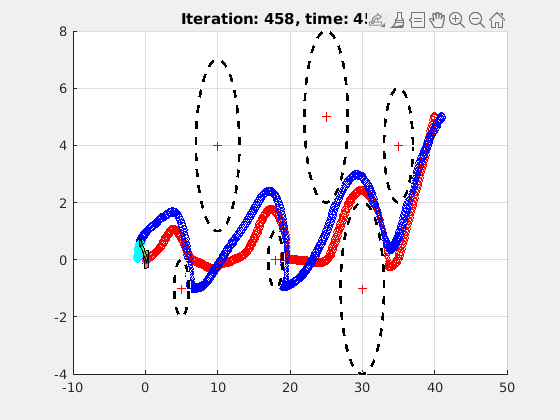

execution_time = 1.8240

execution_time =     1.8240    0.9852


execution_time =     1.8240    0.9852    1.2271


execution_time =     1.8240    0.9852    1.2271    1.0227


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937    0.2094


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937    0.2094    0.1728


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937    0.2094    0.1728    0.1688


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937    0.2094    0.1728    0.1688    0.1872


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937    0.2094    0.1728    0.1688    0.1872    0.1757


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937    0.2094    0.1728    0.1688    0.1872    0.1757    0.1922


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937    0.2094    0.1728    0.1688    0.1872    0.1757    0.1922    0.2071


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937    0.2094    0.1728    0.1688    0.1872    0.1757    0.1922    0.2071    0.2294


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937    0.2094    0.1728    0.1688    0.1872    0.1757    0.1922    0.2071    0.2294    0.1634


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937    0.2094    0.1728    0.1688    0.1872    0.1757    0.1922    0.2071    0.2294    0.1634    0.1934


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937    0.2094    0.1728    0.1688    0.1872    0.1757    0.1922    0.2071    0.2294    0.1634    0.1934    0.1817


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937    0.2094    0.1728    0.1688    0.1872    0.1757    0.1922    0.2071    0.2294    0.1634    0.1934    0.1817    0.1639


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937    0.2094    0.1728    0.1688    0.1872    0.1757    0.1922    0.2071    0.2294    0.1634    0.1934    0.1817    0.1639    0.2133


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937    0.2094    0.1728    0.1688    0.1872    0.1757    0.1922    0.2071    0.2294    0.1634    0.1934    0.1817    0.1639    0.2133    0.2131


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937    0.2094    0.1728    0.1688    0.1872    0.1757    0.1922    0.2071    0.2294    0.1634    0.1934    0.1817    0.1639    0.2133    0.2131    0.1978


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937    0.2094    0.1728    0.1688    0.1872    0.1757    0.1922    0.2071    0.2294    0.1634    0.1934    0.1817    0.1639    0.2133    0.2131    0.1978    0.2580


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937    0.2094    0.1728    0.1688    0.1872    0.1757    0.1922    0.2071    0.2294    0.1634    0.1934    0.1817    0.1639    0.2133    0.2131    0.1978    0.2580    0.2170


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937    0.2094    0.1728    0.1688    0.1872    0.1757    0.1922    0.2071    0.2294    0.1634    0.1934    0.1817    0.1639    0.2133    0.2131    0.1978    0.2580    0.2170    0.1814


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937    0.2094    0.1728    0.1688    0.1872    0.1757    0.1922    0.2071    0.2294    0.1634    0.1934    0.1817    0.1639    0.2133    0.2131    0.1978    0.2580    0.2170    0.1814    0.1665


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937    0.2094    0.1728    0.1688    0.1872    0.1757    0.1922    0.2071    0.2294    0.1634    0.1934    0.1817    0.1639    0.2133    0.2131    0.1978    0.2580    0.2170    0.1814    0.1665    0.2610


execution_time =     1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937    0.2094    0.1728    0.1688    0.1872    0.1757    0.1922    0.2071    0.2294    0.1634    0.1934    0.1817    0.1639    0.2133    0.2131    0.1978    0.2580    0.2170    0.1814    0.1665    0.2610


execution_time = 1×52
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×53
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×54
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×55
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×56
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×57
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×58
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×59
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×60
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×61
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×62
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×63
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×64
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×65
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×66
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×67
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×68
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×69
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×70
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×71
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×72
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×73
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×74
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×75
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×76
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×77
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×78
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×79
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×80
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×81
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×82
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×83
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×84
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×85
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×86
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×87
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×88
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×89
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×90
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×91
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×92
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×93
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×94
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×95
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×96
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×97
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×98
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×99
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×100
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×101
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×102
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×103
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×104
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×105
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×106
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×107
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×108
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×109
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×110
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×111
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×112
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×113
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×114
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×115
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×116
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×117
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×118
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×119
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×120
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×121
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×122
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×123
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×124
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×125
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×126
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×127
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×128
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×129
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×130
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×131
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×132
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×133
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×134
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×135
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×136
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×137
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×138
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×139
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×140
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×141
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×142
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×143
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×144
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×145
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×146
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×147
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×148
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×149
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×150
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×151
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×152
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×153
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×154
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×155
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×156
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×157
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×158
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×159
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×160
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×161
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×162
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×163
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×164
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×165
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×166
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×167
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×168
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×169
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×170
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×171
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×172
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×173
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×174
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×175
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×176
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×177
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×178
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×179
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×180
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×181
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×182
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×183
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×184
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×185
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×186
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×187
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×188
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×189
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×190
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×191
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×192
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×193
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×194
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×195
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×196
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×197
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×198
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×199
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×200
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×201
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×202
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×203
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×204
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×205
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×206
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×207
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×208
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×209
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×210
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×211
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×212
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×213
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×214
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×215
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×216
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×217
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×218
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×219
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×220
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×221
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×222
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×223
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×224
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×225
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×226
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×227
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×228
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×229
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×230
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×231
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×232
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×233
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×234
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×235
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×236
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×237
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×238
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×239
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×240
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×241
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×242
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×243
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×244
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×245
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×246
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×247
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×248
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×249
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×250
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×251
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×252
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×253
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×254
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×255
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×256
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×257
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×258
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×259
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×260
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×261
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×262
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×263
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×264
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×265
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×266
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×267
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×268
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×269
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×270
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×271
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×272
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×273
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×274
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×275
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×276
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×277
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×278
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×279
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×280
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×281
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×282
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×283
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×284
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×285
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×286
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×287
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×288
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×289
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×290
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×291
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×292
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×293
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×294
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×295
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×296
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×297
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×298
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×299
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×300
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×301
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×302
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×303
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×304
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×305
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×306
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×307
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×308
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×309
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×310
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×311
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×312
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×313
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×314
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×315
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×316
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×317
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×318
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×319
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×320
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×321
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×322
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×323
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×324
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×325
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×326
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×327
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×328
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×329
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×330
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×331
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×332
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×333
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×334
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×335
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×336
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×337
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×338
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×339
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×340
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×341
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×342
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×343
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×344
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×345
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×346
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×347
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×348
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×349
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×350
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×351
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×352
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×353
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×354
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×355
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×356
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×357
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×358
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×359
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×360
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×361
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×362
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×363
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×364
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×365
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×366
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×367
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×368
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×369
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×370
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×371
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×372
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×373
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×374
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×375
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×376
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×377
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×378
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×379
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×380
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×381
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×382
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×383
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×384
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×385
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×386
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×387
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×388
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×389
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×390
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×391
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×392
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×393
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×394
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×395
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×396
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×397
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×398
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×399
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×400
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×401
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×402
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×403
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×404
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×405
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×406
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×407
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×408
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×409
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×410
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×411
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×412
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×413
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×414
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×415
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×416
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×417
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×418
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×419
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×420
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×421
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×422
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×423
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×424
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×425
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×426
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×427
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×428
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×429
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×430
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×431
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×432
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×433
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×434
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×435
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×436
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×437
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×438
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×439
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×440
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×441
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×442
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×443
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×444
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×445
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×446
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×447
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×448
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×449
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×450
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×451
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×452
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×453
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×454
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×455
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×456
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×457
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


execution_time = 1×458
    1.8240    0.9852    1.2271    1.0227    0.4834    0.3485    0.2541    0.2434    0.1670    0.2045    0.1846    0.1818    0.1767    0.2132    0.2222    0.1967    0.2213    0.2080    0.1882    0.1885    0.1708    0.3897    0.2186    0.2174    0.2302    0.2068    0.1875    0.2377    0.2275    0.1937


% variable meaning
% x_l, x_f = actual states of leader, follower
% X_L, X_L_stacked = preferred path by leader, 4xN and 4*Nx1 the stacked
% real_d = actual distance between robots

% goal state flag 
goal_reached = false;
i = 1;

% initialization leader and follower STATES
x_l(:,i) = x0;
x_f(:,i) = x0 + [followerParams.d_FL; 0; 0; 0; 0; 0]; % at initial condition we have horizontal disposition with d_FL distance

% vertexes change orientation because of phi
% apply rotation for both robots using the orientation
leaderParams.robotShape = Rmat(x_l(3,i))*leaderParams.initRobotShape;
followerParams.robotShape(:, 1:followerParams.vertexes) = Rmat(x_f(3,i))*followerParams.initRobotShape(:, 1:followerParams.vertexes);

% initial guesses for optimal inputs
U_l_old = zeros([m*N,1]);
U_f_old = zeros([m*N,1]);

figure; 
set(gcf,'Visible','on'); hold on; grid on;
sp = SystemPlotter(leaderParams, followerParams, x_l(:,1), x_f(:, 1), N, obstacles);
% sp = SystemPlotter(leaderParams, followerParams, x_l(:,1), [], N, obstacles);
tit = title("Iteration 1, time: 0s");
% initial rotation of the load
loadTheta = 0;

while (~goal_reached) %&& (i < 500) % terminal condition: goal reach or maximum iteration
    tic

    % calculations of distances between obstacles for leader and follower
    [qi_leader, d_leader] = getObstacleInfo(obstacles, x_l(1:2, i));
    [~, M_leader] = size(qi_leader);
    d_l_min = min(d_leader);

    [qi_follower, d_follower] = getObstacleInfo(obstacles, x_f(1:2, i));
    [~, M_follower] = size(qi_follower);
    d_f_min = min(d_follower);
    
    N1 = 5;
    N2 = 20;
    % selection of the state of the algorithm
    if M_leader == 0
         crit_dist = false;
         N = N2;
    elseif (d_l_min <= leaderParams.rep_dist) | (d_f_min <= followerParams.rep_dist)
        % agents near obstacles, enables obstacle avoidance, need to reduce
        % prediction horizon to be faster
        crit_dist = true;
        if N == N2 % pred horizon changed, need to adapt U_*_old
            N = N1;
            U_l_old = U_l_old(1:m*N);
            U_f_old = U_f_old(1:m*N);
        else
            N = N1;
        end
    else 
        % agents far from obstacles, no need to provide for obstacle
        % avoidance, big prediction horizon 
        crit_dist = false;
        if N == N1 % pred horizon changed, need to adapt U_*_old
            N = N2;
            for s = (N1 + 1):N2
                U_l_old((m*(s-1) + 1):(m*(s-1) + 3)) = U_l_old((m*(N1-1) + 1):(m*(N1-1) + 3));
                U_f_old((m*(s-1) + 1):(m*(s-1) + 3)) = U_f_old((m*(N1-1) + 1):(m*(N1-1) + 3));
            end
        else
            N = N2;
        end
    end
    
    % obtain the next state, the planned path, the identified qis and solver error for leader
    [x_l(:,i+1), X_L, ~, U_l_old] = leaderMPCandUpdate( ...
        plant, x_l(:,i), n, m, N, M_leader, leaderParams, obstacles, qi_leader, U_l_old, crit_dist);
    
    % stack the planned path to supply to the follower, and have it do mpc
    X_L_stacked = reshape(X_L, [n*N, 1]);
    
    %LINEAR follower constraints:
    [x_f(:,i+1), X_F, ~, U_f_old] = followerMPCandUpdate(...
        plant, X_L_stacked, x_f(:,i), n, m, N, M_follower, followerParams, obstacles, qi_follower, U_f_old, loadTheta, leaderParams, crit_dist);
%     %NON-LINEAR follower constraints:
%     [x_f(:,i+1), X_F, qi_follower, ~, U_f_old] = followerMPCandUpdateNC(...
%     plant, X_L_stacked, x_f(:,i), N, followerParams, obstacles, U_f_old);

    if policy_halt 
        % check if trajectory does not loose the load
        formation_error_allt = abs(vecnorm(P*(X_L-X_F))-followerParams.d_FL);
        if any(formation_error_allt(1:k_loose_grip) > eps_loose_grip)
            % obtain the next state, the planned path, the identified qis and solver error for leader
            [x_l(:,i+1), X_L, error, U_l_old] = leaderMPCandUpdateHalt( ...
                plant, x_l(:,i), n, m, N, M_leader, leaderParams, obstacles, qi_leader, zeros([m*N,1]), crit_dist);

            % stack the planned path to supply to the follower, and have it do mpc
            X_L_stacked = reshape(X_L, [n*N, 1]);
            %LINEAR follower constraints:
            [x_f(:,i+1), X_F, ~, U_f_old] = followerMPCandUpdate(...
                plant, X_L_stacked, x_f(:,i), n, m, N, M_follower, followerParams, obstacles, qi_follower, zeros([m*N,1]), loadTheta, leaderParams, crit_dist);
            % %NON-LINEAR follower constraints:
            % [x_f(:,i+1), X_F, qi_follower, ~, U_f_old] = followerMPCandUpdateNC(...
            % plant, X_L_stacked, x_f(:,i), N, followerParams, obstacles, U_f_old);
        end
    end
    % get the instantaneous rotation of load and apply to load and leader
    fl_diff = x_f(:,i+1) - x_l(:,i+1);
    loadTheta = atan2(fl_diff(2), fl_diff(1));
    
    % apply rotation for both robots using the orientation
    leaderParams.robotShape = Rmat(x_l(3,i+1))*leaderParams.initRobotShape;
    followerParams.robotShape(:, 1:followerParams.vertexes) = Rmat(x_f(3,i+1))*followerParams.initRobotShape;
    % apply rotation for the load
    followerParams.loadShape = Rmat(loadTheta)*followerParams.initLoadShape;
    followerParams.robotShape = [followerParams.robotShape(:, 1:followerParams.vertexes), followerParams.loadShape];

    % check if goal was reached up to desired precision
    if norm(x_l(1:2,i+1)) < delta
        goal_reached = true;
    end
    
     % distance between the 2 robots
     real_d(i) = norm(x_l(1:2,i) - x_f(1:2,i));
   
    % do the plotting
    sp.updateLeaderPath(x_l(:,i), X_L);
    sp.updateLoadPos(x_l(:,i), x_f(:,i), loadTheta);
    sp.updateObstacles(obstacles, length(obstacles));
    sp.updateFollowerPath(x_f(:,i), X_F);
    tit.String = "Iteration: "+num2str(i)+", time: "+num2str(i*Ts)+"s";
    sp.redraw();
    
    %Obstacle dynamics 
    obstacles = obstacles_dynamics(obstacles, Ts);  
    
    execution_time(i) = toc % [s]

    % update iteration
    i = i+1;
    
end

tot_ex_time = sum(execution_time);

## Result plot

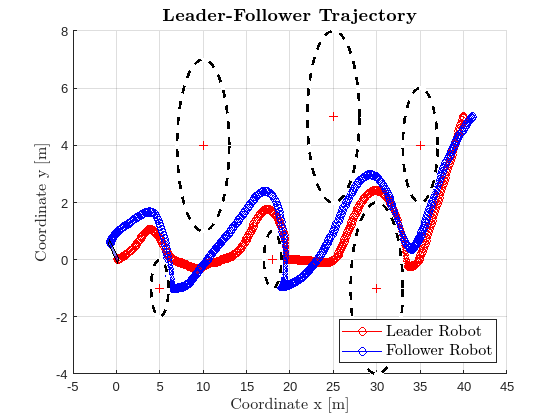

time = 0:Ts:Ts*(i-1);
%Trajectory plot
figure;  hold on; grid on;
plot( x_l(1,:), x_l(2,:), "-o","Color", "red");
plot( x_f(1,:), x_f(2,:), "-o","Color", "blue")
plotObstacles(obstacles);
plot(...
   polyshape(x_f(1,end)+followerParams.loadShape(1,:),...
             x_f(2,end)+followerParams.loadShape(2,:)),...
   'FaceColor',followerParams.pos_color,'FaceAlpha',0.5);
title("\textbf{Leader-Follower Trajectory}","Interpreter","latex", "FontSize", 14)
xlabel("Coordinate x [m]","Interpreter","latex", "FontSize", 12)
ylabel("Coordinate y [m]","Interpreter","latex", "FontSize", 12)
legend("Leader Robot","Follower Robot","Location","southeast","Interpreter","latex", "FontSize", 12)

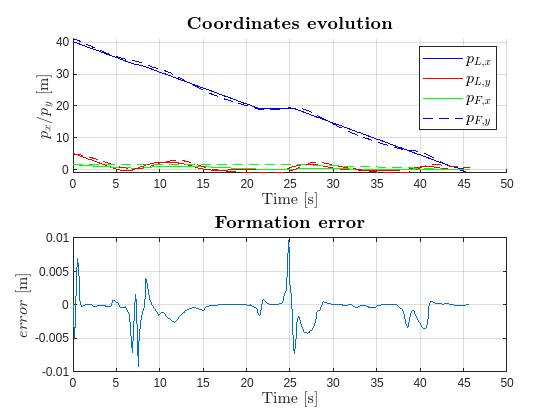


%Coordinates evolution and formation error plot
figure; 
subplot(2,1,1)
hold on; grid on;
plot(time, x_l(1,:), "-b", time, x_l(2,:), "-r", time,  x_l(3,:), "-g");
plot(time, x_f(1,:), "--b", time, x_f(2,:), "--r", time, x_f(3,:), "--g");
xlabel("Time [s]", "Interpreter","latex","FontSize", 12)
ylabel("$p_x$/$p_y$ [m]", "Interpreter","latex", "FontSize", 12)
title("\textbf{Coordinates evolution}", "Interpreter","latex", "FontSize", 14)
legend("$p_{L,x}$","$p_{L,y}$","$p_{F,x}$","$p_{F,y}$","Interpreter","latex", "FontSize", 12)

subplot(2,1,2)
plot(time(1:end-1),real_d - followerParams.d_FL);
grid on;
xlabel("Time [s]", "Interpreter","latex", "FontSize", 12)
ylabel("$error$ [m]", "Interpreter","latex", "FontSize", 12)
title("\textbf{Formation error}", "Interpreter","latex", "FontSize", 14)

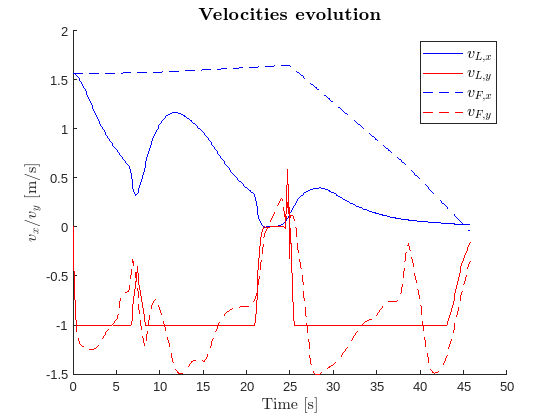


figure;
hold on;
plot(time, x_l(3,:), "-b", time, x_l(4,:), "-r");
plot(time, x_f(3,:), "--b", time, x_f(4,:), "--r");
xlabel("Time [s]", "Interpreter","latex","FontSize", 12)
ylabel("$v_x$/$v_y$ [m/s]", "Interpreter","latex", "FontSize", 12)
title("\textbf{Velocities evolution}", "Interpreter","latex", "FontSize", 14)
legend("$v_{L,x}$","$v_{L,y}$","$v_{F,x}$","$v_{F,y}$","Interpreter","latex", "FontSize", 12)

% PLOTTING DEI VERTICI RISPETTO AGLI OSTACOLI
% for j=1:leaderParams.L
%     dist_l{j} = zeros(length(time), M);
% end
% for o=1:M
%     for j=1:leaderParams.L
%         for t=1:length(time)
%             dist_l{j}(t,o)= norm((x_l(1:2, t)+leaderParams.robotShape(:, j)) - obstacles{o}.center) - obstacles{o}.radius;
%         end
%     end
% end
% for j=1:leaderParams.L
%     figure;
%     hold on;
%     grid on;
%     for o=1:M
%         plot(time, dist_l{j}(:,o));
%     end
% end
% 
% for j=1:followerParams.L
%     dist_f{j} = zeros(length(time), M);
% end
% for o=1:M
%     for j=1:followerParams.L
%         for t=1:length(time)
%             dist_f{j}(t,o)= norm((x_f(1:2, t)+followerParams.robotShape(:, j)) - obstacles{o}.center) - obstacles{o}.radius;
%         end
%     end
% end
% for j=1:followerParams.L
%     figure;
%     hold on;
%     grid on;
%     for o=1:M
%         plot(time, dist_f{j}(:,o));
%     end
% end
% PLOTTING VERTICI NELLO SPAZIO

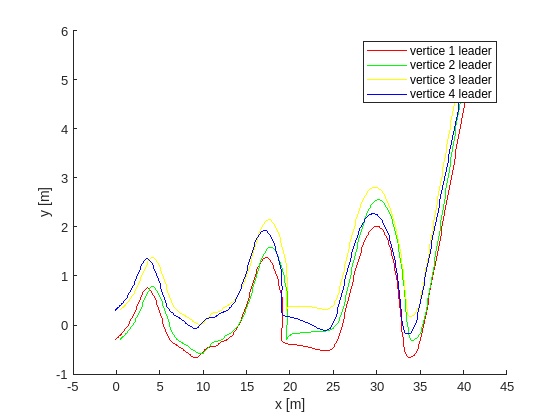

time = 0:Ts:Ts*(i-1);
v_rot_1 = zeros(2,length(time));
v_rot_2 = zeros(2,length(time));
v_rot_3 = zeros(2,length(time));
v_rot_4 = zeros(2,length(time));
figure;
hold on;
for k=1:length(time)
    v_rot_1(1:2, k) = Rmat(x_l(3,k))*leaderParams.initRobotShape(:,1);
end
plot( x_l(1,1:i) + v_rot_1(1,:), x_l(2,1:i) + v_rot_1(2,:), "r");

for k=1:length(time)
    v_rot_2(1:2, k) = Rmat(x_l(3,k))*leaderParams.initRobotShape(:,2);
end
plot( x_l(1,1:i) + v_rot_2(1,:), x_l(2,1:i) + v_rot_2(2,:), "g");

for k=1:length(time)
    v_rot_3(1:2, k) = Rmat(x_l(3,k))*leaderParams.initRobotShape(:,3);
end
plot( x_l(1,1:i) + v_rot_3(1,:), x_l(2,1:i) + v_rot_3(2,:), "y");

for k=1:length(time)
    v_rot_4(1:2, k) = Rmat(x_l(3,k))*leaderParams.initRobotShape(:,4);
end
plot( x_l(1,1:i) + v_rot_4(1,:), x_l(2,1:i) + v_rot_4(2,:), "b");
xlabel("x [m]");
ylabel("y [m]");
legend("vertice 1 leader", "vertice 2 leader", "vertice 3 leader", "vertice 4 leader");


%for k=1:leaderParams.L
%    plot( x_l(1,:) + leaderParams.robotShape(1,k), x_l(2,:) + leaderParams.robotShape(2,k));
%end
% figure;
% hold on;
% for k=1:followerParams.L
%      plot( x_f(1,:) + followerParams.robotShape(1,k), x_f(2,:) + followerParams.robotShape(2,k));
% end